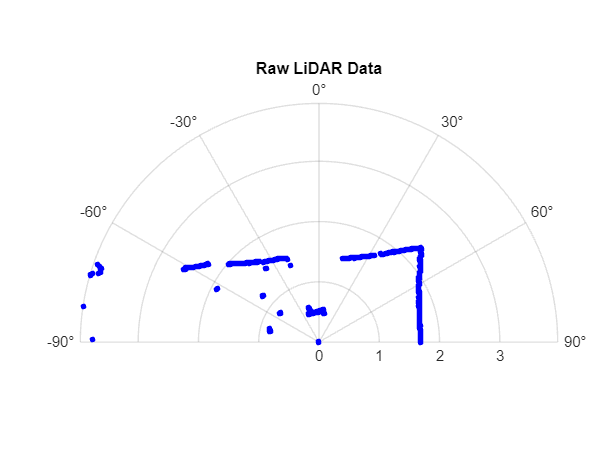

clc; clear;

% --- Load polar LiDAR data ---
polar = readtable('lidar_polar.csv');

% --- Adjust angle frame to match C code (0° = straight ahead) ---
rotated_angles = mod(polar.angle_deg + 120, 360);  % Rotate left 120°
adjusted_angles = rotated_angles - 90;             % Shift so 0° = forward
adjusted_angles(adjusted_angles > 180) = adjusted_angles(adjusted_angles > 180) - 360;
adjusted_angles = -adjusted_angles;                % Flip to correct left/right

% --- Filter field of view: [-90°, +90°] ---
valid_idx = (adjusted_angles >= -90) & (adjusted_angles <= 90);
angles = adjusted_angles(valid_idx);
distances = polar.distance_m(valid_idx);
angles_rad = deg2rad(angles);

% === PLOT 0: Raw LiDAR Data ([-90°, +90°], blue) ===
figure(4); clf;

% Convert raw angles to same frame used in C code
raw_angles = -mod(polar.angle_deg + 120, 360) + 90;
raw_angles(raw_angles > 180) = raw_angles(raw_angles > 180) - 360;
raw_angles_rad = deg2rad(raw_angles);

% Filter to [-90°, +90°]
raw_valid_idx = (raw_angles >= -90) & (raw_angles <= 90);
filtered_angles = raw_angles_rad(raw_valid_idx);
filtered_distances = polar.distance_m(raw_valid_idx);

% Plot
polarscatter(filtered_angles, filtered_distances, 15, 'b', 'filled'); hold on;
title('Raw LiDAR Data');
set(gca, 'ThetaZeroLocation', 'top');
set(gca, 'ThetaDir', 'clockwise');
set(gca, 'ThetaLim', [-90 90]);
rlim([0 max(filtered_distances)]);

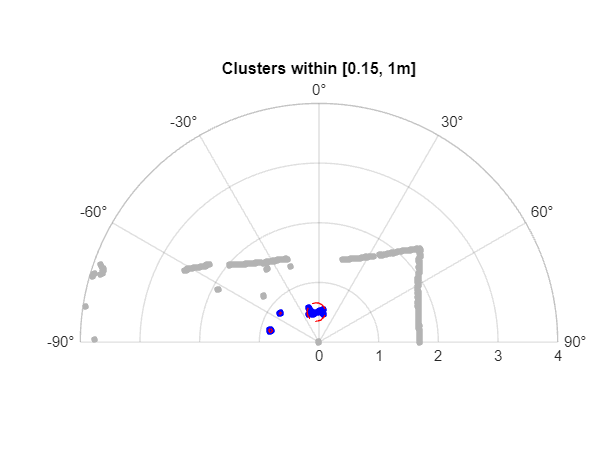



% --- Clustering parameters ---
min_dist = 0.15;
max_dist = 1.0;
min_cluster_size = 5;
angle_res = 0.36;
robot_width = 0.28;

% --- Clustering ---
clusters = {};
current = [];
angle_sum = 0;
dist_sum = 0;
min_d = Inf;
min_a = 0;

for i = 1:length(distances)+1
    if i <= length(distances)
        r = distances(i);
        valid = r > min_dist && r <= max_dist;
    else
        valid = false;
    end

    if ~valid
        if length(current) >= min_cluster_size
            centroid_angle = angle_sum / length(current);
            centroid_dist = dist_sum / length(current);
            clusters{end+1} = struct( ...
                'indices', current, ...
                'centroid_angle', centroid_angle, ...
                'centroid_dist', centroid_dist, ...
                'min_dist', min_d, ...
                'min_angle', min_a, ...
                'count', length(current));
        end
        current = [];
        angle_sum = 0;
        dist_sum = 0;
        min_d = Inf;
    else
        current = [current, i];
        angle_sum = angle_sum + angles(i);
        dist_sum = dist_sum + distances(i);
        if distances(i) < min_d
            min_d = distances(i);
            min_a = angles(i);
        end
    end
end

% --- Select best cluster (largest near 0°) ---
best_idx = -1;
max_size = -1;
for i = 1:length(clusters)
    a = clusters{i}.centroid_angle;
    if clusters{i}.count >= 5 && abs(a) <= 30
        if clusters{i}.count > max_size
            max_size = clusters{i}.count;
            best_idx = i;
        end
    end
end

% === PLOT 1: All clusters ===
figure(1); clf;
polarscatter(angles_rad, distances, 20, [0.7 0.7 0.7], 'filled'); hold on;
title('Clusters within [0.15, 1m]');
set(gca, 'ThetaLim', [-90 90]);
set(gca, 'ThetaZeroLocation', 'top');
set(gca, 'ThetaDir', 'clockwise');

for i = 1:length(clusters)
    idx = clusters{i}.indices;
    theta = deg2rad(angles(idx));
    r = distances(idx);
    polarscatter(theta, r, 20, 'b', 'filled');

    % Draw circle
    [x, y] = pol2cart(theta, r);
    cx = mean(x); cy = mean(y);
    radius = max(sqrt((x - cx).^2 + (y - cy).^2));
    t = linspace(0, 2*pi, 100);
    [xc, yc] = pol2cart(t, radius);
    [tc, rc] = cart2pol(xc + cx, yc + cy);
    polarplot(tc, rc, 'r--');
end

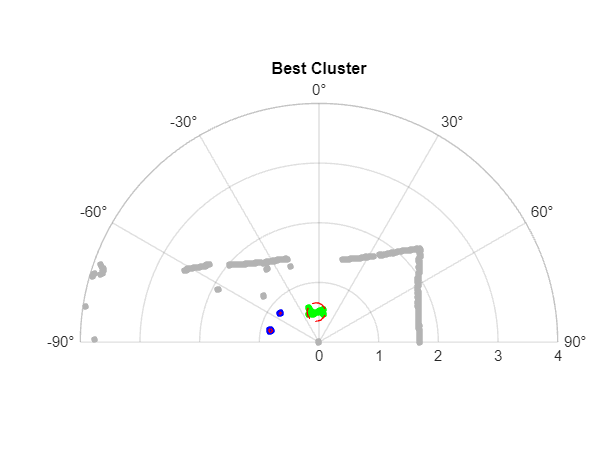


% === PLOT 2: Highlight best cluster ===
figure(2); clf;
polarscatter(angles_rad, distances, 20, [0.7 0.7 0.7], 'filled'); hold on;
title('Best Cluster');
set(gca, 'ThetaLim', [-90 90]);
set(gca, 'ThetaZeroLocation', 'top');
set(gca, 'ThetaDir', 'clockwise');

for i = 1:length(clusters)
    idx = clusters{i}.indices;
    theta = deg2rad(angles(idx));
    r = distances(idx);
    if i == best_idx
        polarscatter(theta, r, 20, 'g', 'filled');
    else
        polarscatter(theta, r, 20, 'b', 'filled');
    end

    % Circle
    [x, y] = pol2cart(theta, r);
    cx = mean(x); cy = mean(y);
    radius = max(sqrt((x - cx).^2 + (y - cy).^2));
    t = linspace(0, 2*pi, 100);
    [xc, yc] = pol2cart(t, radius);
    [tc, rc] = cart2pol(xc + cx, yc + cy);
    polarplot(tc, rc, 'r--');
end

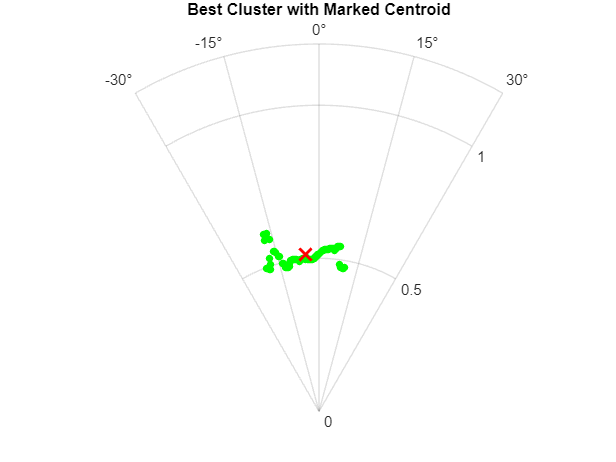


% === PLOT 3: Best cluster with centroid ===
figure(3); clf;
polarscatter(angles_rad, distances, 20, [0.7 0.7 0.7], 'filled'); hold on;
title('Best Cluster with Marked Centroid');
set(gca, 'ThetaZeroLocation', 'top');
set(gca, 'ThetaDir', 'clockwise');
set(gca, 'ThetaLim', [-30 30]);
set(gca, 'RTick', [0 0.5 1.0]);
set(gca, 'ThetaTick', -30:15:30);
rlim([0 1.2]);

if best_idx > 0
    idx = clusters{best_idx}.indices;
    a_deg = angles(idx);
    r = distances(idx);
    keep = (a_deg >= -30) & (a_deg <= 30);
    a_deg = a_deg(keep);
    r = r(keep);
    theta = deg2rad(a_deg);
    polarscatter(theta, r, 25, 'g', 'filled');

    % Mark centroid
    th_c = deg2rad(clusters{best_idx}.centroid_angle);
    r_c = clusters{best_idx}.centroid_dist;
    if clusters{best_idx}.centroid_angle >= -30 && clusters{best_idx}.centroid_angle <= 30
        polarplot(th_c, r_c, 'rx', 'MarkerSize', 12, 'LineWidth', 2);
    end
end